## III. Modelo diferencial de primer orden

Se desea establecer una relación entre las velocidades del efector final y las de las articulaciones. Para ello, es necesario calcular el jacobiano geométrico del robot. Para la construcción del mismo, se hace uso de la siguiente imagen:

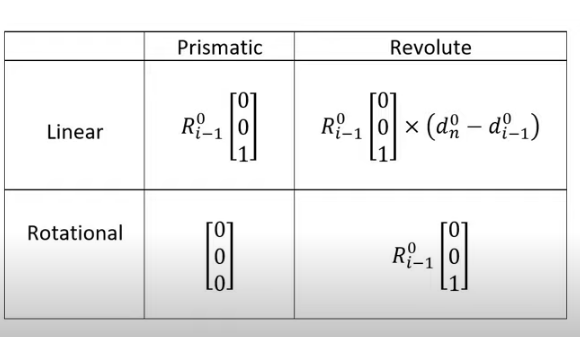

A continuación, se muestra el procedimiento para determinar los valores de las matrices de rotación y de distancias que se mencionan en la tabla: 

syms q1 q2 q3 q4 q5 q6     % Configuraciones del robot simbólicas
threshold = 1e-10;      % Umbral

q = [q1 q2 q3 q4 q5 q6];   % Vector de configuraciones
Rot_total = [];         % Vector para almacenar todas las rotaciones
Trasl_total = [];       % Vector para almacenar todas las posiciones
MTH_aux = 1;            % Valor inicial variable auxiliar MTH
for i = 1:7
    if i<7
        % Calculo de la matriz T_i_i+1
        MTH = mapSymType(L(i).A(q(i)),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
        MTH_aux = MTH_aux*MTH;          % Multiplicación de MTH (0Tn)     
    elseif i==7
        MTH_aux = MTH_aux*Robot.tool;   % Multiplicación con la MTH del efector final
    end
    [Rot Trasl] = tr2rt(MTH_aux);       % Extracción de rotaciones y traslaciones
    Rot_total = [Rot_total Rot];         % Almacenamiento de las rotaciones
    Trasl_total = [Trasl_total Trasl];   % Almacenamiento de las traslaciones
end

Con estos valores, se realizan las operaciones de producto cruz y se contruye la matriz por columnas:

J0 = [];                        % Matriz jacobiana
vel = [];                       % Matriz velocidad

for n = 1:6
    j = (n-1)*3+1;              % Variable para avanzar de 3 en 3      
    vel_ang = Rot_total(:, j:j+2)*[0; 0; 1]; 
    vel_lin = cross(vel_ang, Trasl_total(:,7)-Trasl_total(:,n));       

    vel = [vel_lin; vel_ang];   % Almacenamiento de velocidades
    J0 = [J0 vel];              % Jacobiano
end
J0

Ahora, teniendo en cuenta la primera configuración obtenida en la tabla 2, se hallan los valores de velocidades articulares para las siguientes velocidades en el efector final:

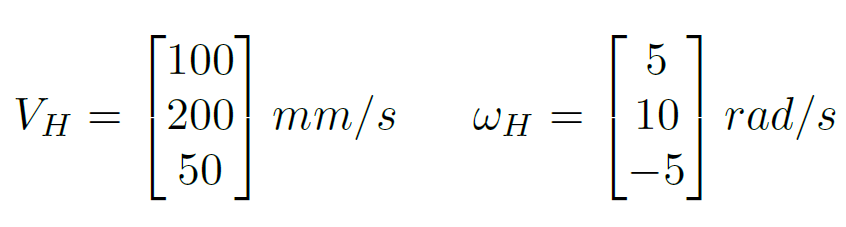

q1=-1.4945;   q2=0.5706;   q3=-0.0324;   q4=-1.8825;    q5=0.5713;    q6=3.0397;
J0_eval=eval(J0)

J0_eval =   457.1967  -55.3432  -24.8734    9.4405   50.2466   -0.0000
   68.5014  723.9639  325.3777   17.9197   25.4871         0
         0  311.0880  567.6531   28.7243  -32.4143    0.0000
         0   -0.9971   -0.9971    0.0654    0.2686    0.5747
         0   -0.0762   -0.0762   -0.8561    0.5098   -0.7657
    1.0000         0         0    0.5126    0.8173    0.2888


VH=[100 200 50]';
omegaH=[5 10 -5]';
Xpunto=[VH; omegaH];
qdotH=inv(J0_eval)*Xpunto

qdotH =     0.4828
    0.1185
    1.2457
  -21.4761
    2.3790
   12.4008
